
Damped pendulum b=0.5 local linearization:


  (theta*,omega*)=(-3.14,0): eig = (-1.281, 0.781)
  (theta*,omega*)=(0.00,0): eig = (-0.250, -0.250)
  (theta*,omega*)=(3.14,0): eig = (-1.281, 0.781)


  Note: at theta*=0, cos=1 -> stable (sink); type depends on b (spiral if b<2).


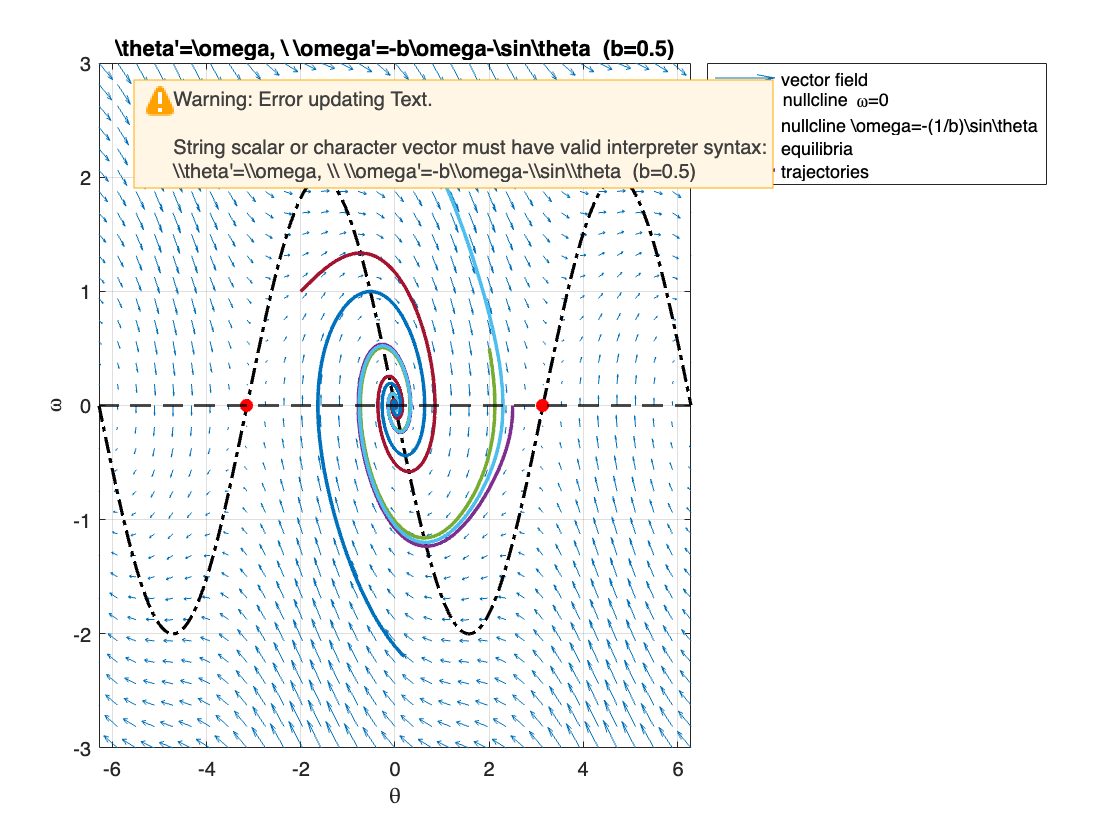


Damped pendulum b=3 local linearization:


  (theta*,omega*)=(-3.14,0): eig = (-3.303, 0.303)
  (theta*,omega*)=(0.00,0): eig = (-0.382, -2.618)
  (theta*,omega*)=(3.14,0): eig = (-3.303, 0.303)


  Note: at theta*=0, cos=1 -> stable (sink); type depends on b (spiral if b<2).


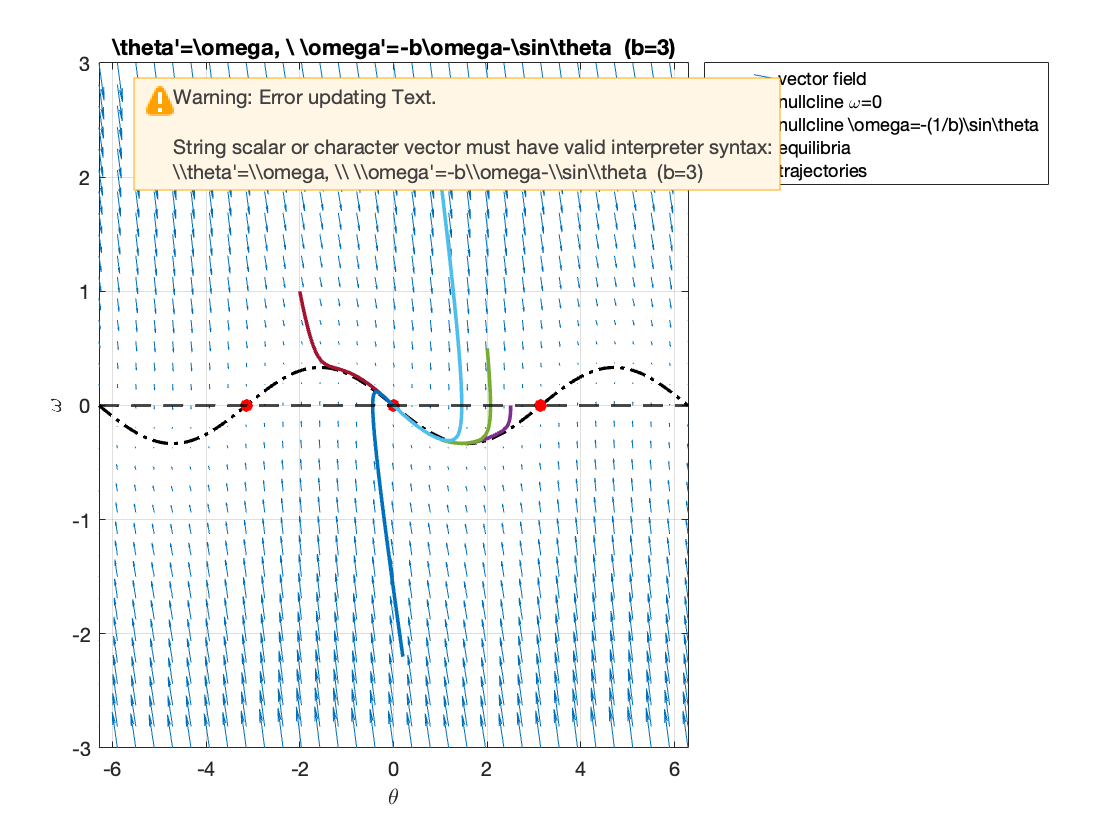

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ex6_pendulum_damped.m
%
% Damped pendulum:
%   theta'' + b theta' + sin(theta) = 0
%
% First-order form:
%   theta' = omega
%   omega' = -b omega - sin(theta)
%
% Goals:
%   - phase portrait with vector field + nullclines + trajectories
%   - local linearization at equilibria: (theta,omega)=(2k*pi,0)
%   - show underdamped vs overdamped behavior by changing b
%
% Note:
%   This is NOT conservative; energy decreases over time.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;

b_list = [0.5, 3.0];   % underdamped (spiral) vs overdamped (node)

thlim = [-2*pi 2*pi];
omlim = [-3 3];

ICs = [ 2.5  0.0;
        2.0  0.5;
        1.0  2.0;
       -2.0  1.0;
        0.2 -2.2];

tspan = [0 25];

for bi = 1:numel(b_list)
    b = b_list(bi);

    f = @(t,z) [ z(2);
                -b*z(2) - sin(z(1)) ];

    % Vector field grid
    [thg,omg] = meshgrid(linspace(thlim(1),thlim(2),33), linspace(omlim(1),omlim(2),33));
    ug = omg;
    vg = -b*omg - sin(thg);

    figure('Color','w','Name',sprintf('Example 6: damped pendulum b=%.2g',b));
    hold on; box on; grid on;
    quiver(thg,omg,ug,vg,'AutoScale','on');
    xlabel('\theta'); ylabel('\omega');
    title(sprintf('\\theta''=\\omega, \\ \\omega''=-b\\omega-\\sin\\theta  (b=%.2g)', b));

    % Nullclines:
    % theta' = 0 -> omega=0
    % omega' = 0 -> -b omega - sin(theta) =0 -> omega = -(1/b) sin(theta)
    yline(0,'k--','LineWidth',1.4);

    th = linspace(thlim(1),thlim(2),800);
    om_null = -(1/b)*sin(th);
    plot(th, om_null, 'k-.','LineWidth',1.6);

    % Equilibrium points in this window: (theta,omega)=(0,0) and (±pi,0)
    eq = [-pi 0; 0 0; pi 0];
    plot(eq(:,1),eq(:,2),'ro','MarkerFaceColor','r','MarkerSize',6);

    % Local linearization:
    % J = [0 1; -cos(theta*) -b]
    fprintf('\nDamped pendulum b=%.2g local linearization:\n', b);
    for k=1:size(eq,1)
        th0 = eq(k,1);
        J = [0 1; -cos(th0) -b];
        lam = eig(J);
        fprintf('  (theta*,omega*)=(%.2f,0): eig = (%.3f, %.3f)\n', th0, lam(1), lam(2));
    end
    fprintf('  Note: at theta*=0, cos=1 -> stable (sink); type depends on b (spiral if b<2).\n');

    % Trajectories
    opts = odeset('RelTol',1e-9,'AbsTol',1e-11);
    for k=1:size(ICs,1)
        z0 = ICs(k,:)';
        [t,z] = ode45(f,tspan,z0,opts);
        %th_wrap = wrapToPi_local(z(:,1));
        plot(z(:,1), z(:,2),'LineWidth',1.8);

        % (Optional) energy decay demo (comment in if you want):
        % E = 0.5*z(:,2).^2 + (1 - cos(z(:,1)));
        % figure(100+bi); hold on; plot(t,E,'LineWidth',1.4);
    end

    xlim(thlim); ylim(omlim);
    legend({'vector field','nullcline \omega=0','nullcline \omega=-(1/b)\sin\theta','equilibria','trajectories'}, ...
        'Location','bestoutside');
end